multiSTEP_2209.sample_time_us = multiSTEP_2209.sample_time_us(:,1)/1000000;
multiSTEP_2209 = renamevars(multiSTEP_2209, "sample_time_us", "time");
multiSTEP_2209 = renamevars(multiSTEP_2209, "pwm_applied_percent", "pwm");
multiSTEP_2209 = renamevars(multiSTEP_2209, "current_mean_a", "currentMEAN");

%Tiempo de muestreo
Ts = multiSTEP_2209.time(2,1) - multiSTEP_2209.time(1,1);
%Entrada al sistema
u = multiSTEP_2209.pwm;
%Salida del sistema
y = multiSTEP_2209.currentMEAN;

% Crear los datos de identificación para la respuesta de corriente
datCurrent = iddata(y, u, Ts);


% Identificar un modelo de corriente a partir de los datos registrados

G10 = tfest(datCurrent,1,0);   % 1 polo
G20 = tfest(datCurrent,2,0);   % 2 polos
G21 = tfest(datCurrent,2,1);   % 2 polos + 1 cero
G22 = tfest(datCurrent,2,2);   % 2 polos + 2 cero


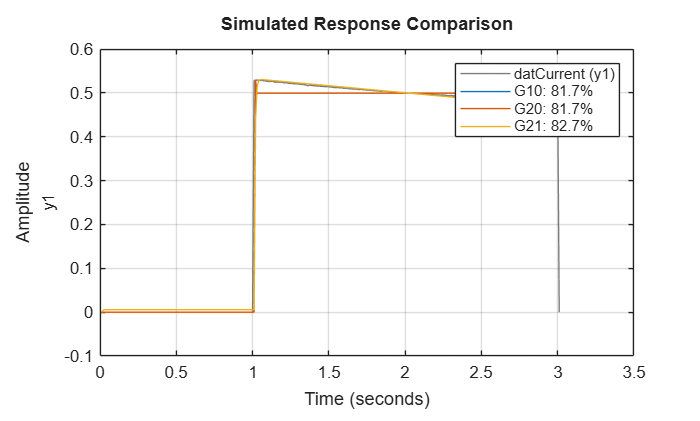

G21_v1 = G21*1.2;
figure

compare(datCurrent,G10,G20,G21)

grid on

G21


G21 =
 
  From input "u1" to output "y1":
       1.15 s - 0.0702
  -------------------------
  s^2 + 174.8 s + 7.538e-06
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: 2   Number of zeros: 1
   Number of free coefficients: 4
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                                
Estimated using TFEST on time domain data "datCurrent".
Fit to estimation data: 82.67%                         
FPE: 0.001759, MSE: 0.001691                           
 
Model Properties


# Sintonizacion de controlador

s = tf('s');
PlantaIdentificada = (1.15*s-0.0702)/(s^2+174.8*s+7.538*10^-6)


PlantaIdentificada =
 
       1.15 s - 0.0702
  -------------------------
  s^2 + 174.8 s + 7.538e-06
 
Continuous-time transfer function.


step